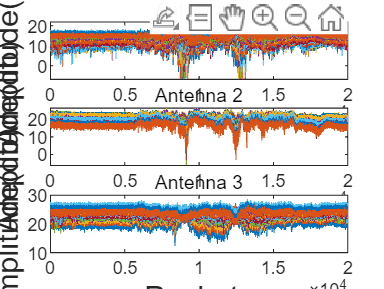

clc
clear
str="input_walk_170303_1334_09.csv";
narry=load(str);
rows = size(narry, 1); % 获取 A 的行数
ant1=narry(1:rows,2:31);
ant2=narry(1:rows,32:61);
ant3=narry(1:rows,62:91);
figure(1)
set(gcf,'position',[150 100 800 600])
subplot(3,1,1)
plot(ant1);
title("Antenna 1")
xlabel('Packets','FontSize', 14)
ylabel('Amplitude(db)','FontSize', 14)
subplot(3,1,2)
plot(ant2);
title("Antenna 2")
xlabel('Packets','FontSize', 14)
ylabel('Amplitude(db)','FontSize', 14)
subplot(3,1,3)
plot(ant3);
title("Antenna 3")
xlabel('Packets','FontSize', 14)
ylabel('Amplitude(db)','FontSize', 14)
%title("振幅随时间的变化")
hold off;

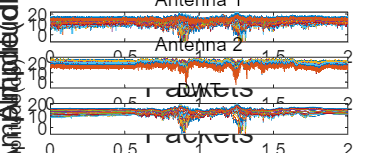

anthampel = zeros(size(ant1));
% 设定hampel滤波器参数
window_size = 10; % 窗口大小，可根据需要调整
num_dev = 4; % 定义异常值的标准偏差范围
for k = 1:30
    % 使用hampel函数进行滤波
    filtered_data0 = hampel(ant1(:, k), window_size, num_dev);
    % 存回到result_matrix
    anthampel(:, k) = filtered_data0;
end
%filtered_data = zeros(size(anthampel));
figure(2)
set(gcf,'position',[150 100 1000 800])

plot(anthampel);
xlabel('Packets')
ylabel('Amplitude(db)')
%title("振幅随时间的变化")
hold off;
filtered_data = zeros(size(anthampel));
vs=zeros(size(anthampel));
for i = 1:30
    filtered_data(:, i) = wden(anthampel(:, i), 'heursure', 's', 'one', 8, 'sym4');
    vs(:, i) = movvar(filtered_data(:, i), 30);
end
% 将去噪后的振幅和相位数据保存回
antdwt = filtered_data;
figure(6);
set(gcf,'position',[100 200 1500 600])
plot(antdwt);
xlabel('Packets');
ylabel('Amplitude(db)');
title('DWT');
hold off;

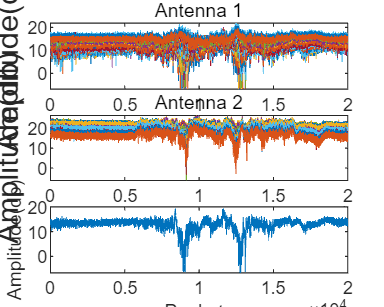

figure(3)
set(gcf,'position',[150 100 1000 800])

plot(ant1(1:rows,3));
xlabel('Packets')
ylabel('Amplitude(db)')
%title("振幅随时间的变化")
hold off;
window_size = 10; % 窗口大小，可根据需要调整
num_dev = 3; % 定义异常值的标准偏差范围
figure(4)
%hampel
x=ant1(1:rows,3);
[y,i,xmedian,xsigma] = hampel(x,window_size,num_dev);% 每四个点值取平均，超出三倍的绝对中位差被认为是异常值
n = 1:rows;
set(gcf,'position',[150 100 1000 800])
plot(n,x)
hold on
%plot(n,xmedian-3*xsigma,n,xmedian+3*xsigma)
plot(find(i),x(i),'sr','MarkerSize', 5, 'LineWidth', 1)
xlabel('Packets')
ylabel('Amplitude(db)')
hold off
legend('Original signal','Outliers')

    % 使用hampel函数进行滤波
filtered_data1 = hampel(x, window_size, num_dev);
    % 存回到result_matrix
  

figure(5)
set(gcf,'position',[150 100 1000 800])

plot(filtered_data1);
xlabel('Packets')
ylabel('Amplitude(db)')
%title("振幅随时间的变化")
hold off;